# Exercício 6

**Alínea a**

T = [0.8 0.2 0 0 0;
    0 0.6 0.3 0.1 0;
    0 0 1 0 0;
    0.3 0.2 0 0.4 0.1;
    0 0 0 0 1;]';

**Alínea b**

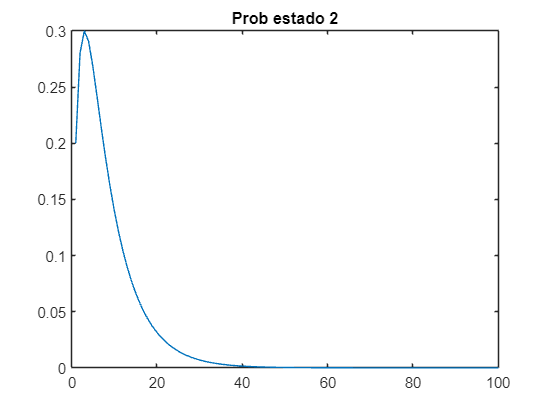

n = 1:100;

vetor = [1;0;0;0;0]; 
probs = zeros(1,length(n));

for i=n
    prob = (T^i)*vetor;
    probs(i)=prob(2);
end

plot(n,probs )
title("Prob estado 2")

**Alínea c**

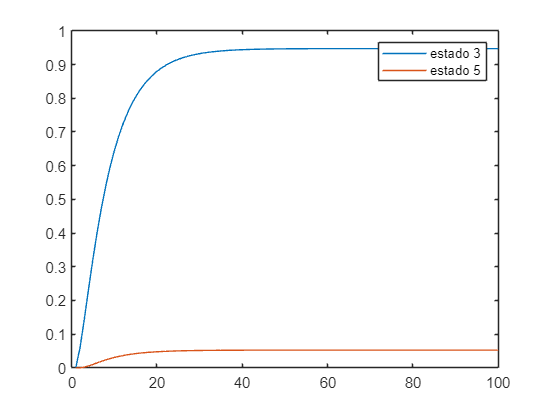

vetor = [1;0;0;0;0];
probs3 = zeros(1,length(n));
probs5 = zeros(1,length(n));

for i=n
    prob = (T^i)*vetor;
    probs3(i)=prob(3);
    probs5(i)=prob(5);
end

plot(n,probs3,n,probs5)
legend('estado 3','estado 5')

**Alínea d**

Tcan = [0.8 0 0.3 0 0 ; 0.2 0.6 0.2 0 0 ; 0 0.1 0.4 0 0 ; 0 0.3 0 1 0 ; 0 0 0.1 0 1]

Tcan =     0.8000         0    0.3000         0         0
    0.2000    0.6000    0.2000         0         0
         0    0.1000    0.4000         0         0
         0    0.3000         0    1.0000         0
         0         0    0.1000         0    1.0000


Q = Tcan(1:3,1:3)

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000


**Alínea e**

% F = (I-Q)^-1
I = eye(length(Q));
F = inv(I-Q)

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053


**Alínea f**

npassos = sum(F);

npassos =     9.4737    4.4737    7.8947


fprintf("Começando no estado 1: %.2f",npassos(1))

Começando no estado 1: 9.47

fprintf("Começando no estado 2: %.2f",npassos(2))

Começando no estado 2: 4.47

fprintf("Começando no estado 4: %.2f",npassos(3))

Começando no estado 4: 7.89

**Alínea g**

R = Tcan(4:5,1:3);
B = R*F;

fprintf("\nComeçando no estado 1:\nprob absrocção estado 3 = %.3f%%\nprob absrocção estado 5 = %.3f%%",B(1,1),B(2,1))


Começando no estado 1:
prob absrocção estado 3 = 0.947%
prob absrocção estado 5 = 0.053%


markov_absorvent_info(T) % Teste de uma função q faz tudo

ans = struct with fields:
                            C: [5×5 double]
                            Q: [3×3 double]
                            R: [2×3 double]
                            F: [3×3 double]
                            B: [2×3 double]
    avg_time_until_absorption: [9.4737 4.4737 7.8947]
                    tr_states: [1 2 4]
                   abs_states: [3 5]
